# Plot Gas Prices

This interaction is not graded. You can move to the next section when you are ready.

countries = readmatrix("./data/gPrices.xlsx", "Sheet", "countries", "OutputType", "string");
prices = readmatrix("./data/gPrices.xlsx", "Sheet", "prices");
Year = readmatrix("./data/gPrices.xlsx", "Sheet", "Year");
whos

  Name            Size            Bytes  Class     Attributes

  Year           19x1               152  double              
  countries       1x10              668  string              
  prices         19x10             1520  double              



## Missing Data Alert

In this task, you will display a warning that notifies users of missing data.

The [`warning`](https://www.mathworks.com/help/matlab/ref/warning.html) function will show the user the warning message you specify. As with `title` and other annotation functions, you can specify the warning inside the function or as a variable that you pass to the function.

`msg` `=` `"This is a warning!"``;`

`warning``(``msg``)`

`Warning: This is a warning!`

`warning``(``"Danger!"``)`

`Warning: Danger!`

Warn users of countries with missing data.

withNan = any(isnan(prices));
warnMsg = "These countries contain missing data: " + join(countries(withNan), ", ");
warning(warnMsg)

## User Input

Select country.

ctry = "Japan";
idxVec = strcmp(ctry, countries);
idx = find(idxVec);

## Price Analysis

Extract data for the chosen country

ctryPrices = prices(:, idx);

Make plot

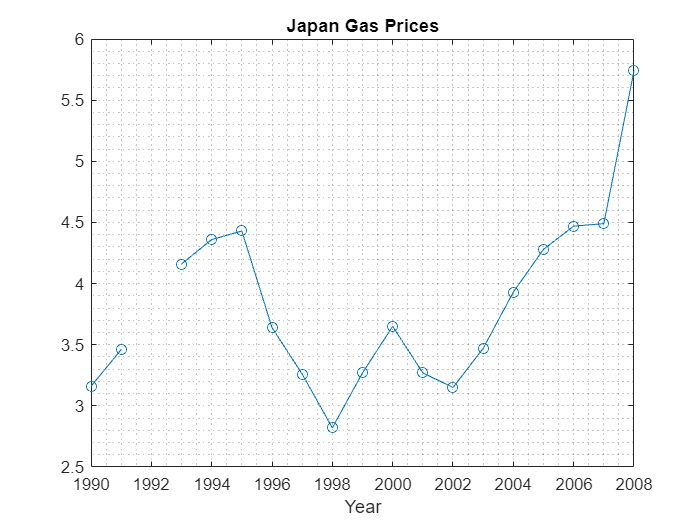

plot(Year,ctryPrices, "o-")
grid minor;
xlabel("Year")
title(ctry + " Gas Prices")

## Analysis Complete Message

It can be helpful to display messages to indicate the status of the program or to provide the user with additional guidance.

You can use the [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) function to display information to the user. Enclose the message in double quotes.

`disp``(``"Message to the user"``)`

`Message` `to` `the` `user`

Inform user of the other countries that can be visualized.

cmpltMsg = "You can also enter the following countries: " + join(countries(~idxVec));
disp(cmpltMsg)

You can also enter the following countries: Australia Canada France Germany Italy Mexico South Korea UK USA
